## Polar Overturning Conceptual Model

#### Live script to run experiments in paper and produce the figures.

#### twnh Aug, Sep '19, Jan–May '20, Sep '20

Must cd to the working directory to run the notebook. The notebook writes pdf figures to the figures directory. Crop them to make publication-ready figures.

Housekeeping:

clear
clear plot_POC_TS_diagram  % Clears persistent variables from this function.
close all
%parpool('MJSProfile1',84) 
if(isempty(gcp))
    %parpool('MJSProfile1',84)
    parpool('local',16) 
end

Exp 1: Northern hemisphere Fram Strait/Barents Sea Opening.

model1 = build_POC_model('NH_FSBSO_can') ;

 Solutions for experiment: [Exp.~1 Fram Strait+BSO] with file suffices: [NH_FSBSO_can]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:                      3.4000          |           35.0000          |            4.7500
 Atlantic Water to shelf:             3.4000          |           35.0000          |   0.1028   0.2689   0.6421
 Polar    Water:                     -1.8675          |           34.3235          |  -1.7039  -1.0863  -0.0000
 Overflow Water:             1.2043   1.4288   1.5674 |  34.9022  34.9549  35.0714 |  -4.7261  -3.6699  -3.0705
 Shelf    Water:            -1.9941  -2.0607  -2.2015 |  36.4907  37.6234  40.0000 |  -0.5902  -0.2291  -0.0747
 Ambient

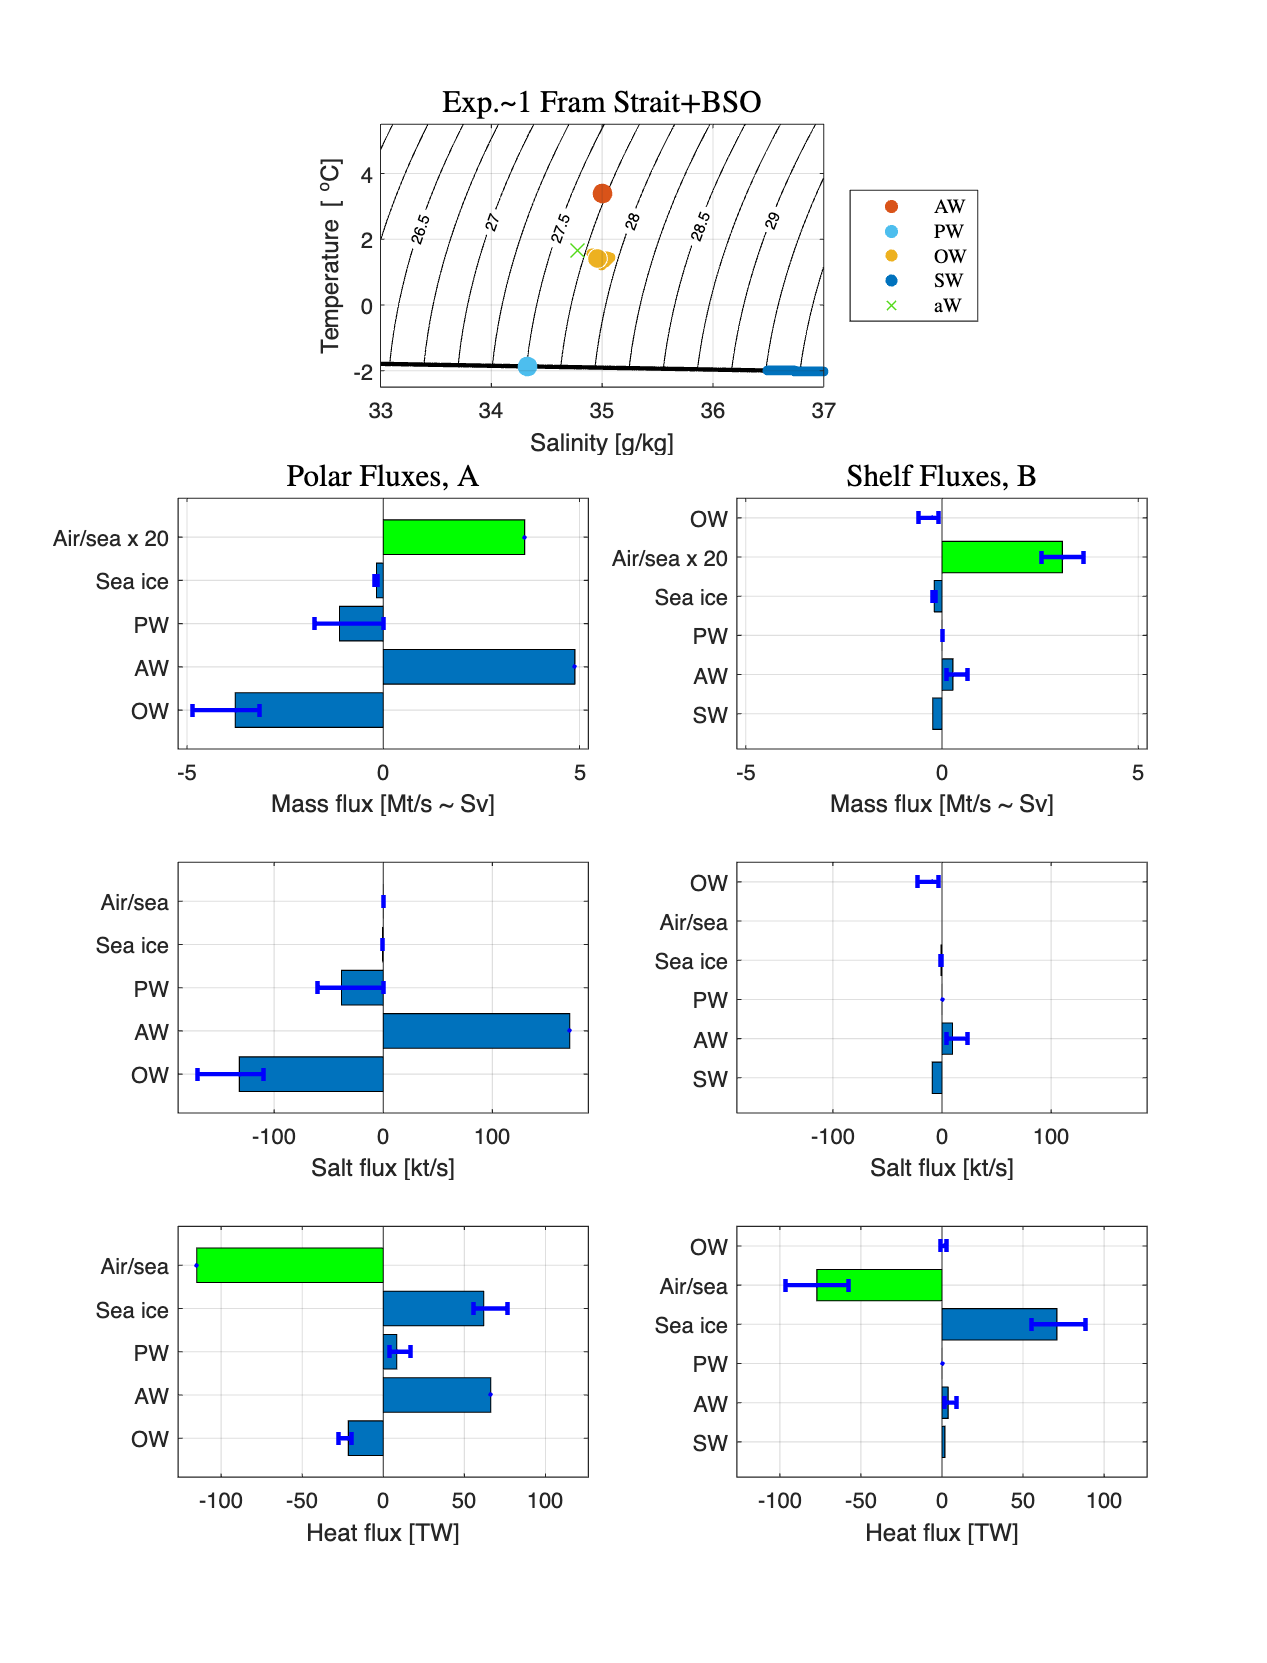

Error using matlab.graphics.internal.name
Unable to create output file 'figures/solution_NH_FSBSO_can.pdf', No such file or directory.

Error in print (line 71)
pj = matlab.graphics.internal.name( pj );

Error in plot_POC_solution (

plot_POC_solution(model1)

Exp 2: Modified Northern hemisphere Fram Strait/Barents Sea Opening (higher Q).

model2 = build_POC_model('NH_FSBSO_mod') ;
plot_POC_solution(model2) ;

Make figure showing entrainment/shelf circulation tradeoff

plot_POC_tradeoff(model1,model2)

Exp 3: Northern hemisphere Fram Strait/Barents Sea Opening with many Q values.

model3 = build_POC_model('NH_FSBSO_range') ;
plot_POC_solutions1(model3,model1,model2) ;

Exp 4: Northern hemisphere Fram Strait/Barents Sea Opening with wide range of all parameters.

model4 = build_POC_model('NH_FSBSO_sens') ;
plot_POC_solutions2(model4,model3,model1,model2)

Compare numerical results to theory

plot_POC_solutions_and_theory(model4)

Exp 5: Northern hemisphere Fram Strait/Barents Sea Opening with various S_2 values.

model5 = build_POC_model('NH_FSBSO_S2_range') ;
plot_POC_solutions3(model5,model1)

Exp 6: Southern hemisphere.

model6 = build_POC_model('SH_can') ;
plot_POC_solution(model6)

Exp V: Southern hemisphere with warm AW following reviewer 2.

modelV = build_POC_model('SH_mod') ;
plot_POC_solution(modelV)

Exp W: Eldevik & Nilsen (2013) parameters

modelW = build_POC_model('NH_FSBSO_EN13') ;
plot_POC_solution(modelW)

Exp X: Modified Northern hemisphere Fram Strait/Barents Sea Opening (intermediate Q).

modelX = build_POC_model('NH_FSBSO_int') ;
plot_POC_solution(modelX)

Exp Y: Modified Northern hemisphere Fram Strait/Barents Sea Opening (small S2).

modelY = build_POC_model('NH_FSBSO_small_S2') ;
plot_POC_solution(modelY)

Exp Z: Southern hemisphere with many Q values

modelZ = build_POC_model('SH_range') ;
plot_POC_solutions1(modelZ,model6,model6)